## step1


lx = 36; % 0~140，每4mm一个点
ly = 36; % 0~140，每4mm一个点
lphi = 19; % 0°~180°，每10°一个点
lsita = 21; % -20°~20°，每2°一个点
Total = lx*ly*lphi*lsita;%总数

## step2

Data = zeros(Total,4);
parfor k = 1:size(EM1,1)
    if EM1(k) == 1
        % k值换算成位置和角度
        mx = 4*floor(k/(ly*lphi*lsita));
        my = 4*floor(mod(k,(ly*lphi*lsita))/(lphi*lsita));
        mphi = 10*floor(mod(mod(k,(ly*lphi*lsita)),(lphi*lsita))/lsita);
        msita = 2*mod(mod(mod(k,(ly*lphi*lsita)),(lphi*lsita)),lsita) - 20;
        Data(k,:) = [mx,my,mphi,msita];
    end
end
Data_0 = zeros(size(Data));

parfor k = 1:size(Data,1)
    if Data(k,4) ~= 0
        Data_0(k,:) = Data(k,:);
    end
end
Data_0(:,3) = Data_0(:,3).*sign(Data_0(:,4));
Data_0(:,4) = 180 - abs(Data_0(:,4)); % 转化为资料上的格式

## step3

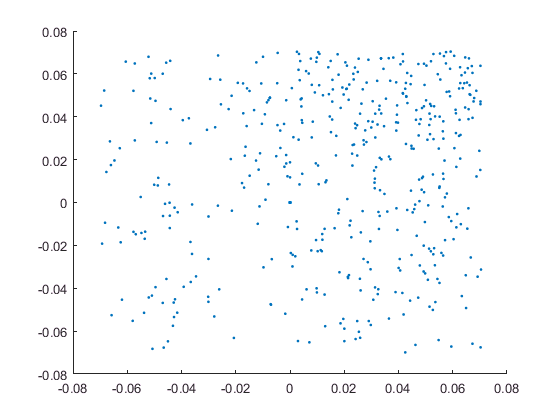

Danger = zeros(Total,1);
parfor k = 1:Total
    l = floor(k/(Total/9)) + 1;
    Danger(k) = fun_Danger_range(l,Data_0(k,:));
end
M2 = EMP.*Danger;
scatter(M2(:,1),M2(:,2),'.');

sum(Danger) 

ans = 480

## step4

D_K = zeros(9,1);%分区计数
for k = 1:9
    D_K(k) = sum(Danger((k - 1)*(Total/9) + 1 : k*(Total/9)));
end

## step5

Bata = zeros(Total,4);
D_0 = zeros(9,1);
parfor k = 1:Total
        % k值换算成位置和角度
        mx = 4*floor(k/(ly*lphi*lsita));
        my = 4*floor(mod(k,(ly*lphi*lsita))/(lphi*lsita));
        mphi = 10*floor(mod(mod(k,(ly*lphi*lsita)),(lphi*lsita))/lsita);
        msita = 2*mod(mod(mod(k,(ly*lphi*lsita)),(lphi*lsita)),lsita) - 20;
        Bata(k,:) = [mx,my,mphi,msita];
end
Bata_0 = zeros(size(Bata));

parfor k = 1:Total
    if Bata(k,4) ~= 0
        Bata_0(k,:) = Bata(k,:);
    end
end
Bata_0(:,3) = Bata_0(:,3).*sign(Bata_0(:,4));
Bata_0(:,4) = 180 - abs(Bata_0(:,4)); % 转化为资料上的格式
Danger_0 = zeros(Total,1);
parfor k = 1:Total
    l = floor(k/(Total/9)) + 1;
    Danger_0(k) = fun_Danger_range(l,Bata_0(k,:));
end
for k = 1:9
    D_0(k) = sum(Danger_0((k - 1)*(Total/9) + 1 : k*(Total/9)));
end
D_K'